# Optimal Prediction from Data: an AR(1) Process

## The AR(1) Process

Consider an $AR(1)$ stationary stochastic process, described by the spectral canonical model

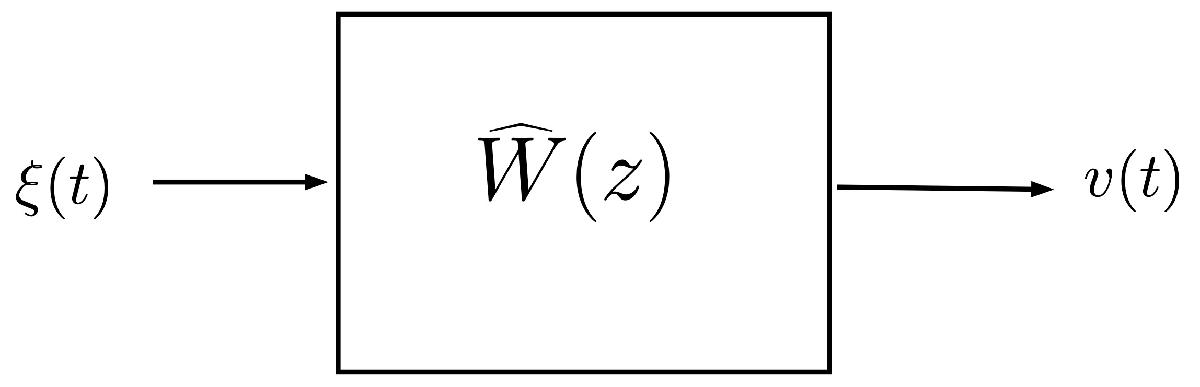

where 


$$\widehat{W}(z) = \displaystyle \frac{1}{1-a\,z^{-1}}\;,\quad \vert a\vert <1 \;, \qquad \xi(\cdot) \sim \text{WN}\left(0,\, \lambda^2_{\xi}\right)$$


Hence the difference equation describing the process in the time domain is


$$v(t) = a\,v(t-1)+\xi(t)$$


### The $k$-Steps Ahead Predictor

The long division algorithm, performed for one, two, and three steps leads to the following results:

One step: 


$$\widehat{W}(z) =1+ \displaystyle \frac{a\,z^{-1}}{1-a\,z^{-1}} = 1+z^{-1}\,\left[ \displaystyle \frac{a}{1-a\,z^{-1} } \right] 
\quad \Longrightarrow \quad \widehat{W}_1(z) = \displaystyle \frac{a}{1-a\,z^{-1} }$$


Two steps: 


$$\widehat{W}(z) =1+ a\,z^{-1}+\displaystyle \frac{a^2\,z^{-2}}{1-a\,z^{-1}} = 1+ a\,z^{-1}+z^{-2}\,\left[ \displaystyle \frac{a^2}{1-a\,z^{-1} } \right]
\quad \Longrightarrow \quad 
\widehat{W}_2(z) =\displaystyle \frac{a^2}{1-a\,z^{-1} } $$


Three steps: 


$$\widehat{W}(z) =1+ a\,z^{-1}+a^2\,z^{-2} + \displaystyle \frac{a^3\,z^{-3}}{1-a\,z^{-1}} = 1+ a\,z^{-1}+a^2\,z^{-2}+z^{-3}\,\left[ \displaystyle \frac{a^3}{1-a\,z^{-1} } \right]
\quad \Longrightarrow \quad 
\widehat{W}_3(z) =\displaystyle \frac{a^3}{1-a\,z^{-1} } $$


$r$-steps ahead:


$$\begin{array}{rcl}
\widehat W(z) &=& 1+a z^{-1} + a^2 z^{-2}+\cdots+z^{-r} \, \frac{a^r }{1-a\,z^{-1}} \\
&=& 1+a z^{-1} + a^2 z^{-2}+\cdots+a^{r-1}\,z^{-r+1} + z^{-r} \,\left[ \frac{a^r }{1-a\,z^{-1}} \right] 
\end{array}
\quad \Longrightarrow \quad \widehat{W}_r(z) = \frac{a^r }{1-a\,z^{-1}} $$


### The Variance of the Prediction Error

The variance of the prediction error is given by

One step:


$$\text{var} \left[\epsilon \right] = \lambda^2_{\xi}$$


Two steps:


$$\text{var} \left[\epsilon \right] = (1+a^2)\,\lambda^2_{\xi}$$


Three steps:


$$\text{var} \left[\epsilon \right] = (1+a^2+a^4)\,\lambda^2_{\xi}$$


$r$ steps ahead:


$$\text{var} \left[\epsilon \right] = (1+a^2+a^4+\cdots+a^{2(r-1)})\,\lambda^2_{\xi}$$


### Optimal Predictor from Data

The *whitening filter* is given by


$$\widetilde{W}(z) = \displaystyle \big[\widehat{W}(z)\big]^{-1} = \displaystyle \frac{A(z)}{1} = 1-a\,z^{-1}$$


Thus, the optimal predictor from data is                                             $W_{r}(z) = \widetilde{W}(z) \cdot \widehat{W}_r(z)$

One step:                                                                                                $W_1(z) = a \quad \Longrightarrow \quad \hat{v}\left(t+1 \vert t \right) = a \,v(t)$

Two steps:                                                                                               $W_2(z) = a^2 \quad \Longrightarrow \quad \hat{v}\left(t+2 \vert t \right) = a^2 \,v(t)$

Three steps:                                                                                            $W_3(z) = a^3 \quad \Longrightarrow \quad \hat{v}\left(t+3 \vert t \right) = a^3 \,v(t)$

$r$ steps ahead:                                                                                        $W_r(z) = a^r \quad \Longrightarrow \quad \hat{v}\left(t +r\vert t \right) = a^r \,v(t)$

## Hands-On: The $k$-Steps Ahead Predictor

clear
close all
clc

Consider an $AR(1)$ stationary process 

a = -0.739; % select the AR parameter

Moreover, configure the stationary white noise process feeding in the $AR$ filter

lambda2_xi = 1.3% the noise variance

lambda2_xi = 1.3000

Choose how much AR process data you want to simulate and collect:

Ndata = 150; 

Let's estimate how long is the initial transient output of the filter:

zero_threshold = 1e-8; 
% let's assume that the value is practically zero if less than or equal to zero_threshold
Ntransient = 5*(ceil(log10(zero_threshold)/log10(abs(a)))+10); 

N_TOT_data = Ndata + Ntransient;

Now simulate and collect the data

xi_data = sqrt(lambda2_xi) * randn(N_TOT_data,1);

vTOT = zeros(N_TOT_data,1);
vTOT(1) = xi_data(1); % initial condition ofr the AR(1) r.v.

for t=2:N_TOT_data
    vTOT(t) = a*vTOT(t-1)+xi_data(t);
end % for t

v = vTOT(Ntransient+1:end); % blowing away the transient part

Evaluating the predictions of the one-step ahead and of the two-steps ahead predictors

v1TOT = zeros(size(vTOT)); % the array containing the 1-step ahead predictor values
v2TOT = zeros(size(vTOT)); % the array containing the 2-steps ahead predictor values

for t=2:N_TOT_data
    v1TOT(t) = a*vTOT(t-1); % 1-step ahead predictor
end % for t

for t=3:N_TOT_data
    v2TOT(t) = a*a*vTOT(t-2); % 2-steps ahead predictor
end % for t

v1 = v1TOT(Ntransient+1:end); % blowing away the transient part
v2 = v2TOT(Ntransient+1:end); % blowing away the transient part

var_v1 = lambda2_xi;
var_v2 = lambda2_xi*(1+a*a);

Choose the order of a $k$-steps ahead predictor ($3 \le k \le 20$) to compare the performance with those of the others predictors

k_steps = 6; % the order of the k-steps ahead predictor

and evaluate the prediction

vkTOT = zeros(size(vTOT)); % the array containing the k-steps ahead predictor values
ak = a.^(k_steps);
for t=(k_steps+1):N_TOT_data
    vkTOT(t) = ak*vTOT(t-k_steps); % k-steps ahead predictor
end % for t

vk = vkTOT(Ntransient+1:end); % blowing away the transient part

var_vk = 0;
for kk=1:k_steps
    var_vk = var_vk+a.^(2*(kk-1));
end % for kk
var_vk = var_vk*lambda2_xi;


Plotting the $AR(1)$ process realization toghether with the one-step, two-steps and three-steps predictor outputs.

Let's take into considerations also the expected value $\text{E}[v(t)]=\bar v=0$

bar_v = 0; % the expected value of the r.v. v

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.8]);
plot(v, 'LineStyle','-', 'LineWidth', 1.5, 'Marker','o', 'MarkerSize', 9, ...
         'MarkerEdgeColor',[0, 0.4470, 0.7410],...
         'MarkerFaceColor',[0, 0.4470, 0.7410], 'Color',[0, 0.4470, 0.7410]);
grid on
hold on
xlabel('Time instant $t$ [sample]', 'Interpreter', 'latex');
ylabel('$AR(1)$ samples $v(t)$', 'Interpreter','latex');

plot(v1, 'LineStyle','-', 'LineWidth', 1.5, 'Marker','square', 'MarkerSize', 7, ...
          'MarkerEdgeColor',[0.8500 0.3250 0.0980],...
    'MarkerFaceColor',[0.8500 0.3250 0.0980], 'Color',[0.8500 0.3250 0.0980]);

high_threshold_v1 = (+3*sqrt(var_v1)).*ones(size(v1));
low_threshold_v1 = (-3*sqrt(var_v1)).*ones(size(v1));
plot(v1+high_threshold_v1, 'LineStyle',':', 'LineWidth', 1.5, 'Color',[0.8500 0.3250 0.0980]);
plot(v1+low_threshold_v1, 'LineStyle',':', 'LineWidth', 1.5, 'Color',[0.8500 0.3250 0.0980]);

%p = patch('XData', [1:Ndata,  Ndata:-1:1], 'YData', [v1-3*sqrt(var_v1) fliplr(v1+3*sqrt(var_v1))])

plot(v2, 'LineStyle','-', 'LineWidth', 1.5, 'Marker','^', 'MarkerSize', 7,...
           'MarkerEdgeColor',[0.9290 0.6940 0.1250],...
            'MarkerFaceColor',[0.9290 0.6940 0.1250], 'Color',[0.9290 0.6940 0.1250]);

high_threshold_v2 = (+3*sqrt(var_v2)).*ones(size(v2));
low_threshold_v2 = (-3*sqrt(var_v2)).*ones(size(v2));
plot(v2+high_threshold_v2, 'LineStyle','--', 'LineWidth', 1.5, 'Color',[0.9290 0.6940 0.1250]);
plot(v2+low_threshold_v2, 'LineStyle','--', 'LineWidth', 1.5, 'Color',[0.9290 0.6940 0.1250]);

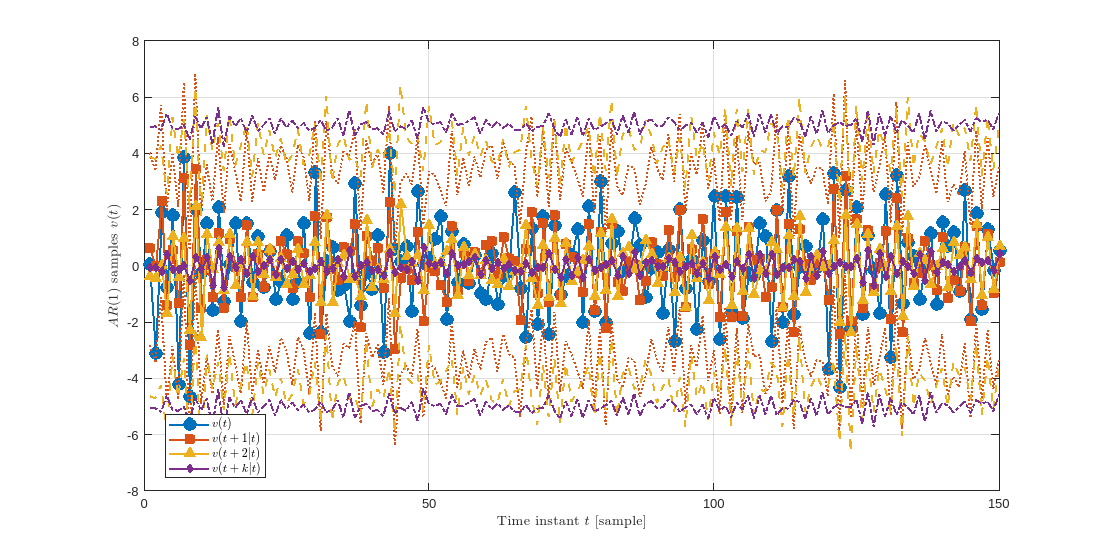

plot(vk, 'LineStyle','-', 'LineWidth', 1.5, 'Marker','diamond', 'MarkerSize', 5,...
           'MarkerEdgeColor',[0.4940 0.1840 0.5560],...
            'MarkerFaceColor',[0.4940 0.1840 0.5560], 'Color',[0.4940 0.1840 0.5560]);

high_threshold_vk = (+3*sqrt(var_vk)).*ones(size(vk));
low_threshold_vk = (-3*sqrt(var_vk)).*ones(size(vk));
plot(vk+high_threshold_vk , 'LineStyle','-.', 'LineWidth', 1.5, 'Color',[0.4940 0.1840 0.5560]);
plot(vk+low_threshold_vk, 'LineStyle','-.', 'LineWidth', 1.5, 'Color',[0.4940 0.1840 0.5560]);

legend('$v(t)$', '$v(t+1|t)$', '','','$v(t+2|t)$', '','','$v(t+k|t)$', '','', 'Interpreter', 'latex', ...
    'Location', 'best')

### Using Several Predictions at Once

Given the AR(1) process under consideration, let us consider the N samples collected. How will the process evolve? We use the samples to provide one-step forward, two-step forward etc. estimates.

Simply, we can estimate the future evolution (with respect to the time instant $N$) of the $AR(1)$ process by using the one-step predictor, the two-steps predictor and so on, all applied to the observation obtained at time instant $N$


$$\hat{v}\left(N+1 \vert t \right) = a \,v(N) \quad \hat{v}\left(N+2 \vert N\right) = a^2 \,v(N) \quad \cdots \quad  \hat{v}\left(N+r \vert N\right) = a^r \,v(N) \quad \cdots$$


Consider the r.v. $v(t)$ at the time instant $t=N$ and then evaluate the predictors

vN = v(end); % pick the last collected value of the r.v.

pred_H = 11; % select the prediction horizon

v_pred = zeros(size(pred_H,1));   % preallocate the array devoted to store the predictions
var_vpred = zeros(size(pred_H,1));% preallocate the array devoted to store the variance of each prediction

dummy_v = 0; % temporary storage, useful when evaluating recursively the prediction variances
for k=1:pred_H
    v_pred(k) = (a.^k)*vN; % the k-steps ahead predicted value
    var_vpred(k) = dummy_v + +a.^(2*(k-1));
    dummy_v = var_vpred(k);
end % for k
var_vpred = var_vpred * lambda2_xi;

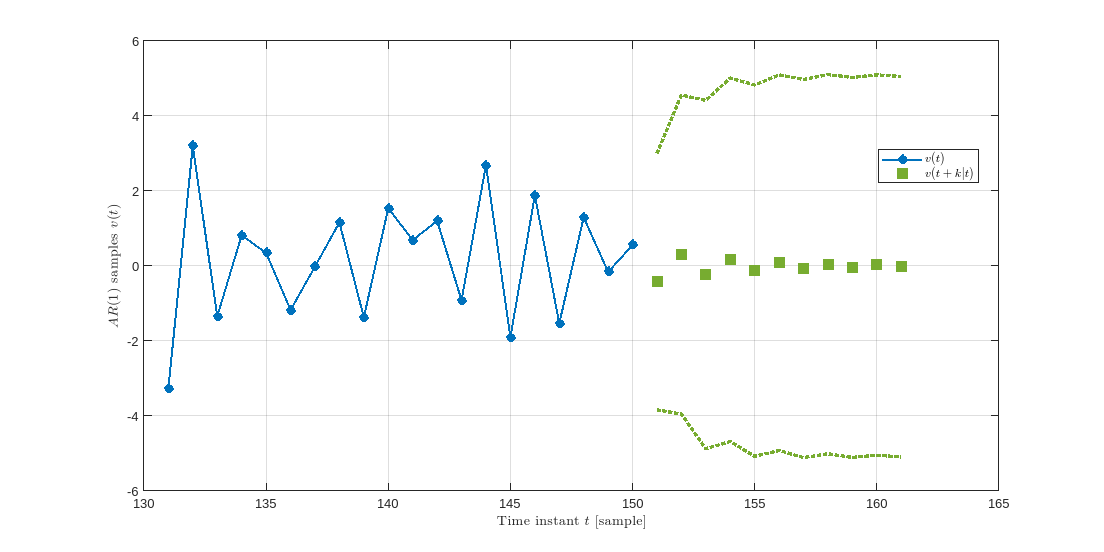

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.8]);
% consider the last M data only
M = 20;
Ninit = Ndata - M+1;
timeInstants = (Ninit:Ndata);
AR_vM = v(Ninit:end);
plot(timeInstants, AR_vM, 'LineStyle','-', 'LineWidth', 1.5, 'Marker','o', 'MarkerSize', 6, ...
         'MarkerEdgeColor',[0, 0.4470, 0.7410],...
         'MarkerFaceColor',[0, 0.4470, 0.7410], 'Color',[0, 0.4470, 0.7410]);
grid on
hold on
xlabel('Time instant $t$ [sample]', 'Interpreter', 'latex');
ylabel('$AR(1)$ samples $v(t)$', 'Interpreter','latex');

future_timeSteps = (Ndata+1:Ndata+pred_H);
plot(future_timeSteps, v_pred, 'LineStyle','none','Color',[0.4660 0.6740 0.1880], 'Marker','square', ...
    'MarkerSize', 9, 'MarkerFaceColor', [0.4660 0.6740 0.1880], 'MarkerEdgeColor', [0.4660 0.6740 0.1880]);
high_threshold_vk = (+3*sqrt(var_vpred));
low_threshold_vk = (-3*sqrt(var_vpred));
plot(future_timeSteps,v_pred+high_threshold_vk , 'LineStyle',':', 'LineWidth', 2.5, 'Color',[0.4660 0.6740 0.1880]);
plot(future_timeSteps,v_pred+low_threshold_vk, 'LineStyle',':', 'LineWidth', 2.5, 'Color',[0.4660 0.6740 0.1880]);
legend('$v(t)$', '$v(t+k|t)$', '','', 'Interpreter', 'latex', ...
    'Location', 'best')